# Autonomous Valet Service

The objective of this code is to develop a self driving parking service. Matlab provides an autonomous self driving parking example [online](https://www.mathworks.com/help/driving/examples/automated-parking-valet.html).

This code will use the above example as a base and try to reproduce the result on any map.

% Configuarable Parameters
parking_spot = 4;
road_file_path = 'ParkingLines/polylines9.shp';
parking_points_file_path = 'ParkingSpots/points6.shp';
car_width  = 0.000005;
car_length = 0.00002;

## Setting up Map for the Example

The "extra" add to the original code is using actual coordinates of real world structures. In this example we are using a parking lot at the University of Southern California, Los Angeles.

The map is generated using KML from Google Earth.

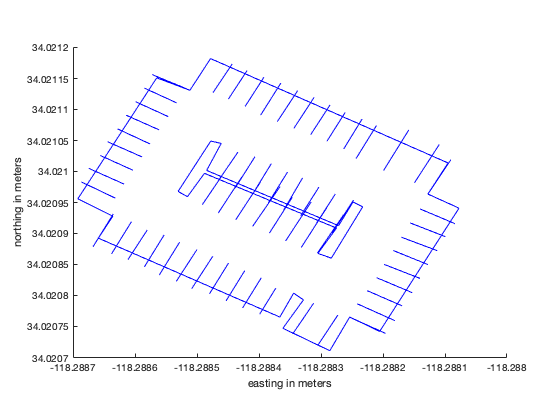

road_f = shaperead(road_file_path);
points_f = shaperead(parking_points_file_path);

figure
ran_map = mapshow(road_f);
xlabel('easting in meters')
ylabel('northing in meters')

### Initializing Cost Map

Given the map we must create three images, 

- Containing wall: Hard requirement is that we do not crash against these walls

- Parking lines: Soft requirements, Keeps us on the path to the spot

- Cars in the lot: Hard requirement we must not crash against any car.

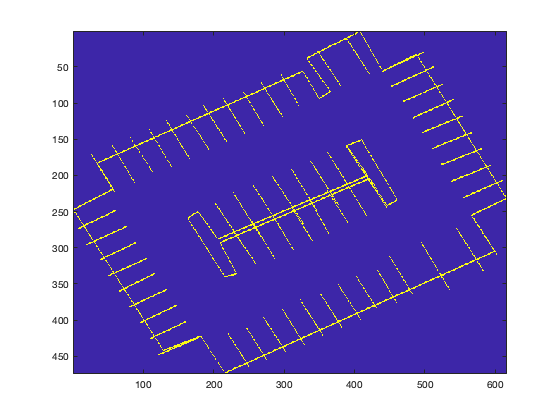

%% Get bounds of the map
info = shapeinfo(road_file_path);
boundary_bounds = info.BoundingBox;
min_col = boundary_bounds(1, 1);
min_row = boundary_bounds(1, 2);
max_col = boundary_bounds(2, 1);
max_row = boundary_bounds(2, 2);
% fprintf("pt_0 = (%d, %d)\n", min_row, max_col);
% fprintf("pt_1 = (%d, %d)\n", max_row, min_col);

cost_map = generateCostMap(road_f, max_row, min_row, max_col, min_col);


image(cost_map);

## Estimating the State of the Car

The state of the car is given by [x, y, theta]

Although it is easy to estimate the coordinates of the car given the map, the main challenge is estmating the orentation of the car that point.

### Car at parking Spots

The point_f variable give us the coordinates of the spots. 

Assigning parking points to their named index

points_l = size(points_f, 1);
entrance_state = zeros(1, 3);
exit_state = zeros(1, 3);
parking_spots = zeros(points_l - 2, 3);
for i = 1:points_l
    if contains(points_f(i).NAME ,"Parking")
        spot_id = sscanf(points_f(i).NAME, "Parking #%d");
        parking_spots(spot_id, 1) = points_f(i).X;
        parking_spots(spot_id, 2) = points_f(i).Y;
    elseif points_f(i).NAME == "Entrance"
        entrance_state(1, 1) = points_f(i).X;
        entrance_state(1, 2) = points_f(i).Y;
    elseif points_f(i).NAME == "Exit"
        exit_state(1, 1) = points_f(i).X;
        exit_state(1, 2) = points_f(i).Y;
    end
    
end

To give us the orientation, we will need to use the road_f variable as well. The road_f contains a corresponding line, (Lane #i) to give the orientation.

road_l = size(road_f, 1);
SCALE = 0.000001;
rows = ceil((max_row - min_row)/SCALE);
cols = ceil((max_col - min_col)/SCALE);
for i = 1:road_l
    road_i = road_f(i);
    x_0 = normalize_val(road_i.X(1), min_col, max_col, cols);
    x_1 = normalize_val(road_i.X(2), min_col, max_col, cols);
    y_0 = normalize_val(road_i.Y(1), min_row, max_row, rows);
    y_1 = normalize_val(road_i.Y(2), min_row, max_row, rows);
    m = (y_1 - y_0)/ (x_1 - x_0);
    orientation = atan(m);
    if contains(road_i.NAME ,"Lane")
        spot_id = sscanf(road_i.NAME, "Lane #%d");
%         p_spot = [parking_spots(spot_id, 1), parking_spots(spot_id, 2)];
%         if norm([x_0, y_0] - p_spot) < norm([x_1, y_1] - p_spot)
%             orientation = orientation - pi;
%         end
        parking_spots(spot_id, 3) = orientation;
    elseif road_i.NAME == "Entrance"
        entrance_state(1, 3) = orientation;
    elseif road_i.NAME == "Exit"
        exit_state(1, 3) = orientation;
    end 
end

## Plot Car States at each Spots

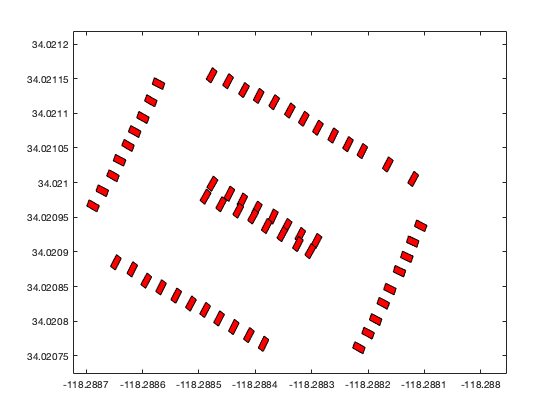

figure
parking_spot_l = size(parking_spots, 1);
for i = 1:parking_spot_l
    parking_i = parking_spots(i, :);
    front_x = parking_i(1);
    front_y = parking_i(2);
    front_t = parking_i(3);
    left_front_x = front_x - (car_width  * sin(pi - front_t));
    left_front_y = front_y - (car_width * cos(pi - front_t));
    
    right_front_x = front_x + (car_width  * sin(pi - front_t));
    right_front_y = front_y + (car_width * cos(pi - front_t));
    
    rear_x = front_x - (car_length * cos(front_t));
    rear_y = front_y - (car_length * sin(front_t));
    
    left_rear_x = rear_x - (car_width  * sin(pi - front_t));
    left_rear_y = rear_y - (car_width * cos(pi - front_t));
    
    right_rear_x = rear_x + (car_width  * sin(pi - front_t));
    right_rear_y = rear_y + (car_width * cos(pi - front_t));
    
    x_fill = [left_front_x, right_front_x, right_rear_x, left_rear_x];
    y_fill = [left_front_y, right_front_y, right_rear_y, left_rear_y];
    
    p_1 = [front_x, front_y];
    p_2 = [rear_x, rear_y];
    dp = p_2 - p_1;
%     quiver(p_1(1),p_1(2),dp(1),dp(2),0);
%     hold on;
    fill(x_fill, y_fill, 'r');
    hold on;
end

## Path Planning from entrance to a Parking Lot

### Support Function

We need to normalize the points and translate to the cost map equiv

#### Normalize Row

function [normed_val] = normalize_val(val, min_val, max_val, to_val)
    normed_val = ceil(((val - min_val)/(max_val - min_val)) * to_val) + 1;
end

#### Generate Cost Map

function [cost_map] = generateCostMap(path_f, max_row, min_row, max_col, min_col)
    %% Initialize cost map
    SCALE = 0.000001;
    rows = ceil((max_row - min_row)/SCALE);
    cols = ceil((max_col - min_col)/SCALE);
    cost_map = zeros(rows, cols);
    
    %% Fill Cost map
    road_l = size(path_f);
    
    % For each path
    for idx = 1:road_l
        
        % Get each pair of lines
        road_i = path_f(idx);
        line_l = size(road_i.X, 2);
        for pair = 1:line_l-2
            x_0 = normalize_val(road_i.X(pair), min_col, max_col, cols);
            x_1 = normalize_val(road_i.X(pair+1), min_col, max_col, cols);
            y_0 = normalize_val(road_i.Y(pair), min_row, max_row, rows);
            y_1 = normalize_val(road_i.Y(pair+1), min_row, max_row, rows);
    %       fprintf("pt_0 = (%d, %d)\n", x_0, y_0);
    %       fprintf("pt_1 = (%d, %d)\n", x_1, y_1);
            m = (y_1 - y_0)/(x_1 - x_0);
            c = y_1 - m*x_1;
    %       fprintf("y = %fx + %f\n", m, c);
            x_st = x_0;
            x_en = x_1;
            if x_1 < x_0
                x_st = x_1;
                x_en = x_0;
            end
            % List out all points in the line
            for col_i = x_st:x_en
                row_i = ceil(m*col_i + c);
                cost_map(row_i, col_i) = 255;
                row_i = floor(m*col_i + c);
                cost_map(row_i, col_i) = 255;
    %           fprintf("(%d, %d)\n", row_i, col_i);
            end
        end
    end
end